## 1D field visualization

TODO

- add GAUSS, LINEAR

- interp not working

- lower the grid resolution

generate map

grid = OctoGrid(2,2,2,10);

% add wall
grid.addBox(0.7,0.8,0,0.8,0.2,1.5)

generate phase

y = 0.001:0.001:1.999

y =     0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


sample map

map_list = [];

x = 1;
z = 1;

% list of obstacle values
map_list = [map_list grid.grid(ceil(y*grid.resolution), x*grid.resolution, z*grid.resolution)];

draw map plot

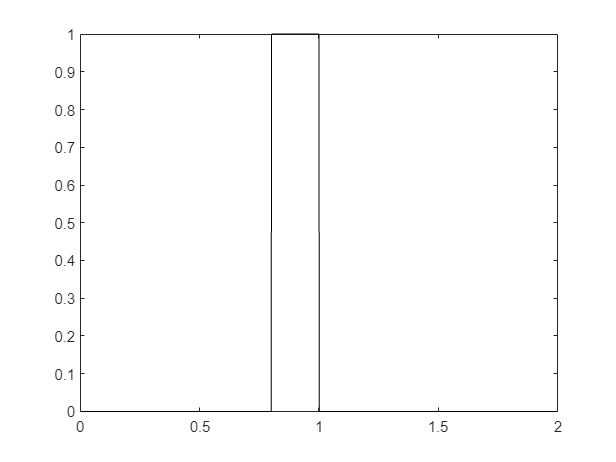

figure()
plot(y, map_list,'black')
hold on

generate kernels

rep_kernels = REP_kernels();

sigma = 3

draw grid on plot the size of resolution

generate LINEAR, GAUSS, LINEAR+INTERP, GAUSS+INTERP samples

rep_values = [];
tic()
for i = y
    rep_values = [rep_values REP_field_calculation(grid, rep_kernels, [x,i,z])'];
end
toc()

Elapsed time is 2.693673 seconds.


plot samples

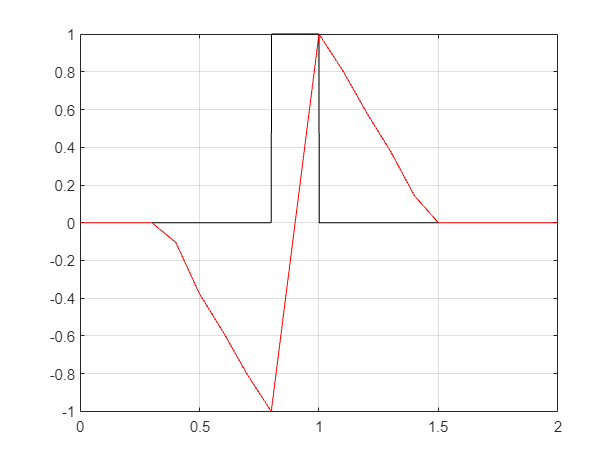

plot(y, (rep_values(2,:))/max(rep_values(2,:)),'red')
grid on
hold on

add legend

## 2D / 3D field visualization

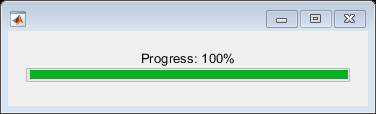

x = 0.1:0.01:2;
y = 0.1:0.01:2;

rep_values_2Dx = [];
rep_values_2Dy = [];

% Initialize waitbar
h = waitbar(0, 'Progress: 0%');

for i = y
    rep_values_1D = [];
    for j = x
%         tic()
        rep_values_1D = [rep_values_1D REP_field_calculation(grid, rep_kernels, [j,i,z])'];
%         toc()
    end
    rep_values_2Dx = [rep_values_2Dx ; rep_values_1D(1,:)];
    rep_values_2Dy = [rep_values_2Dy ; rep_values_1D(2,:)];

    % Update progress bar
    waitbar(i / y(end), h, sprintf('Progress: %d%%', round(i / y(end) * 100)));
end

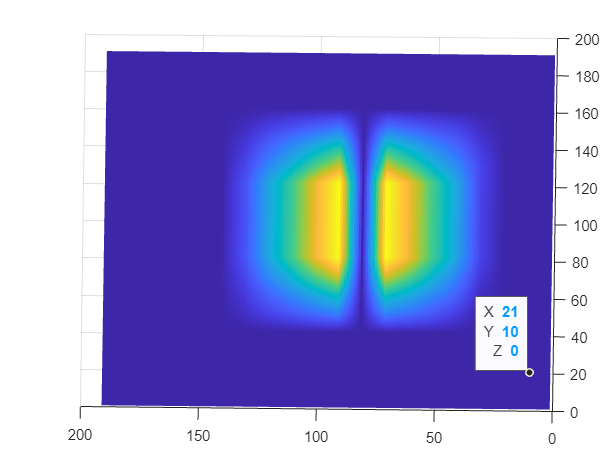

figure()
surf(abs(rep_values_2Dy), 'EdgeColor', 'none')